## Import data

create storage

RMSstorage=zeros(1001,36,5);
delta=0.01;
if delta==0.1
    zetastore=[1.25,2.5,5,10,20,40];
elseif delta==0.01
    zetastore=[12.5,25,50,100,200];
end

import data

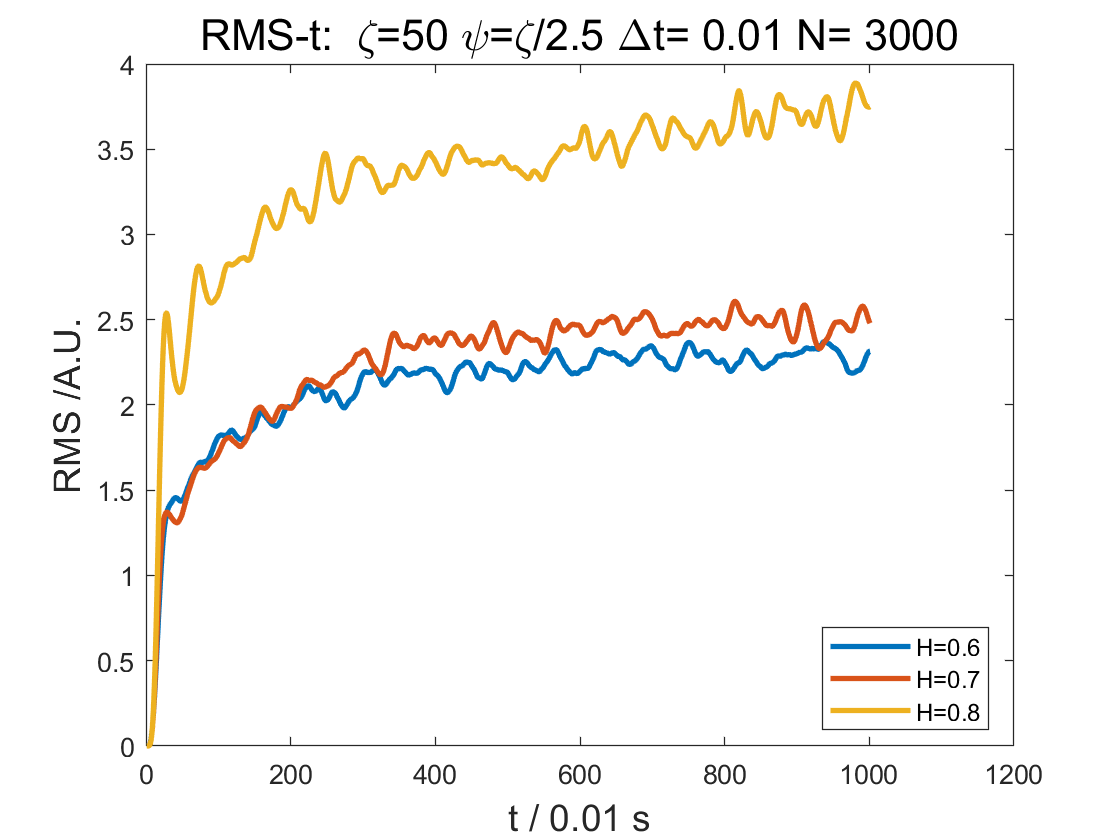

Total_experiment_number=3000;
X=1:1001;
figure
for zeta=50
    for psi=[zeta/2.5]
        for H=[0.6,0.7,0.8]
            load(['C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\v4_1\data\RMSdata.H=',num2str(H), ...
                '.zeta=',num2str(zeta),'.psi=',num2str(psi),'.N=',num2str(Total_experiment_number),'.mat']);
            plot(X,RMSX,'LineWidth',2)
            hold on
        end
    end
end
xlabel(['t / ',num2str(delta),' s'],'FontSize',14);
ylabel('RMS /A.U.','FontSize',14);
legend('H=0.6','H=0.7','H=0.8','location','best')
title(['RMS-t: ',' \zeta=',num2str(zeta),' \psi=\zeta/2.5',' \Deltat= ',num2str(delta), ...
            ' N= ',num2str(Total_experiment_number)],'FontSize',16);